# 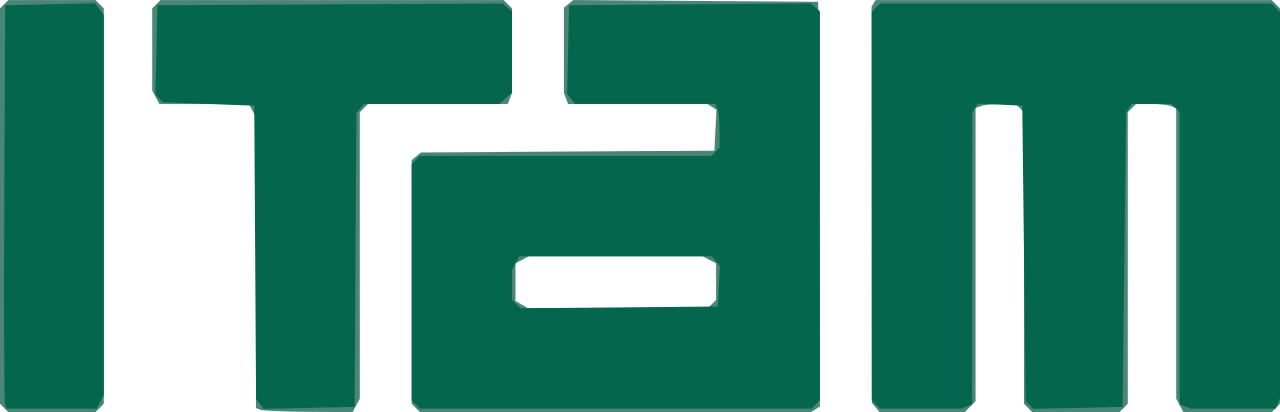

# Proyecto 1

# Algoritmos Numéricos por Computadora

# Criptografía de llave pública RSA

Larissa Trasviña 166280

Regina Vigil  174567

Federico Cortés 173721

## INTRODUCCIÓN:

La criptografía asimétrica es el método ciptográfico que usa un par de claves para el envío de mensajes. Las dos claves pertenecen a la misma persona que recibirá el mensaje. Una clave es pública y se puede entregar a cualquier persona, la otra clave es privada y el propietario debe guardarla de modo que nadie tenga acceso a ella. Además, los métodos criptográficos garantizan que esa pareja de claves solo se puede generar una vez, de modo que se puede asumir que no es posible que dos personas hayan obtenido casualmente la misma pareja de claves.

Un mensaje cifrado con la clave pública de un destinatario no puede ser descifrado por nadie (incluyendo al que lo cifró), excepto un poseedor de la clave privada correspondiente, presumiblemente su propietario y la persona asociada con la clave pública utilizada. Su función es garantizar la confidencialidad del mensaje.

En criptografía RSA (Rivest, Shamir y Adleman) es un sistema criptográfico de clave pública desarrollado en 1979. Es el primer y más utilizado algoritmo de este tipo. La seguridad de este algoritmo radica en el problema de la factorización de números enteros. Los mensajes enviados se representan mediante números, y el funcionamiento se basa en el producto, conocido, de dos números primos grandes elegidos al azar y mantenidos en secreto. 

## DESARROLLO:

El algoritmo consta de tres pasos: generación de claves, cifrado y descifrado.

1. Se seleccionan dos números primos largos **P **y **Q** de forma aleatoria y se calcula el producto **N=P*Q**. A esta **N** se le denomina módulo.

2. Se elige un número **D**, menor que el valor de **N** calculado anteriormente y que sea relativamente primo al producto de: 

*(P-1)(Q-1)*

3. Se calcula un número entero **E** que esté dentro del rango * 1<=E<=(P-1)(Q-1)*

con la operación     *                          E*D= 1mod[(P-1)(Q-1)]*

4.  Ahora a **D** y **E **se les conoce como los exponentes privado y público respectivamente.

5. La clave pública la formarán la pareja** (N,E)**

6. La clave privada viene dada por **(N,D)**

7. Con la clave pública procederíamos a encriptar el mensaje deseado y con la privada se desencintaría.

8. El factor **P** y **Q** debe ser guardado o destruido para evitar que cualquiera intente romper el juego de llaves, con esta se podría obtener la clave privada.

## CÓDIGO:

disp('Criptografía de llave pública');

%Input value of p and q
p = input('p: ');
q = input('q: ');

disp('Inicializando:');
n=p*q; %Calcular valor de n (multiplicación de números primos)
tf=(p-1)*(q-1); %Calculate value of totien function

%Calcular el valor de e
x=2;e=1;
while x > 1
    e=e+1;
    x=gcd(tf,e);%Buscar la división más grande 
end

%Calcular valor de d
i=1;
d=0;
while i > 0
    d = d+1;
    x = e*d;
    x = mod(x,20);
    if x == 1
       i = 0; 
    end
end

%clc;
disp(['(p): ' num2str(p)]);
disp(['(q): ' num2str(q)]);
disp(['(N): ' num2str(n)]);
disp(['Totien function (tf): ' num2str(tf)]);
disp(['Public key (e): ' num2str(e)]);
disp(['Private key (d): ' num2str(d)]);

P = input('input (p): ','s');
c = double(P);
disp('disp (p): ');
disp(P);

disp('disp: ');
disp(c);

%Encrypt

cipher= power(c,e);
cipher= mod(cipher,n);

disp('cipher: ');
disp(cipher);

%Decrypt
plain= power(cipher,d);
plain= mod(plain,n)+33;

disp('decrypt: ');
disp(plain);

disp('decrypt: ');
disp(char(plain));%Convert double to char 

## CONCLUSIONES: